# Figure 3 on events (with associated supplemental figures)

## PLS plots

d = SessManager.load_special('Mouse2022');
alpha = 0.02;

[X, ks] = d.get_dataset;
X_shuf = shuffle(X, ks);
X_z = zscore(X);
X_shuf_z = zscore(X_shuf);
[XS, stats, origin] =...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);
XS_s = (X_shuf_z - mean(X_shuf_z)) * stats.W;
origin_s = -mean(X_shuf_z) * stats.W;

Using one session from Mouse2022, showing real data:

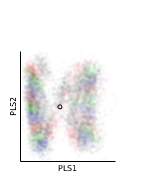

figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
Utils.printto('events_figs/f3_events', 'PLS_events_real.pdf');

And shuffled data:

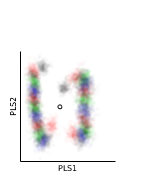

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
Utils.printto('events_figs/f3_events', 'PLS_events_shuf.pdf');

## Signal and noise

s_inds = SessManager.special_sessions_usable_index({'Mouse2022', 'Mouse2024', 'Mouse2028'});
get_usable_result = @(idx) load(onefile(['records_adjacent_metrics_events_transients/*_' num2str(idx, '%.3d') '_*']));

res = cell(1,numel(s_inds));
for s_ix = 1:numel(s_inds)
    res{s_ix} = get_usable_result(s_inds(s_ix));
end

cutoff = 100;
asymp_line = @(n,m) Utils.fitaline(n,m,cutoff);
res_lookup = @(res, code)...
    cellfun(@(x)...
    cellfun(@(y)...
    median(y{code(1),code(2:3)}),...
    x.results_table),...
    res,'UniformOutput',false);


n = cellfun(@(x)x.n_sizes, res, 'UniformOutput', false);
signal = res_lookup(res, 'mse');
noise = res_lookup(res, 'mce');
noise_shuf = res_lookup(res, 'mue');

snr = cellfun(@rdivide, signal, noise,...
    'UniformOutput', false);
snr_shuf = cellfun(@rdivide, signal, noise_shuf,...
    'UniformOutput', false);

[signal_slope, signal_slope_conf] = cellfun(asymp_line, n, signal,...
    'UniformOutput', false);
[noise_slope, noise_slope_conf] = cellfun(asymp_line, n, noise,...
    'UniformOutput', false);
[noise_shuf_slope, noise_shuf_slope_conf] = cellfun(asymp_line, n, noise_shuf,...
    'UniformOutput', false);

[asymp_snr, asymp_snr_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_slope, noise_slope_conf);
[asymp_snr_shuf, asymp_snr_shuf_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_shuf_slope, noise_shuf_slope_conf);

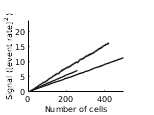

dff2_lim = [0 24];
figure;
MultiSessionVisualizer.plot_single_filtered(n, {signal}, {'k'}, [true true true]);
ylim(dff2_lim);
xlabel 'Number of cells'
ylabel 'Signal ([event rate]^2)'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'signal_events.pdf');

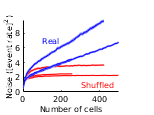


figure;
MultiSessionVisualizer.plot_single_filtered(n, {noise_shuf, noise}, {'r', 'b'}, [true true true]);

text(100, 7, 'Real', 'Color', 'b');
text(300, 1, 'Shuffled', 'Color', 'r');
xlabel 'Number of cells'
ylabel 'Noise ([event rate]^2)'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'noise_events.pdf');

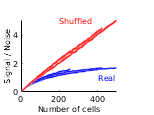


figure;
MultiSessionVisualizer.plot_single_filtered(n, {snr, snr_shuf}, {'b', 'r'}, [true true true]);
text(200, 5, 'Shuffled', 'Color', 'r');
text(400, 1, 'Real', 'Color', 'b');
xlabel 'Number of cells'
ylabel 'Signal / Noise'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'snr_events.pdf');

signal_and_noise_analysis

function [quotient, quotient_uncertainty] = uncertain_divide(x, xc, y, yc)
quotient = x./y;
quotient_uncertainty = abs(x./y)*sqrt((xc./x).^2 + (yc./y).^2);
end